# Register Images Using Registration Estimator App

This example shows how to align a pair of images using the [**Registration Estimator**](docid:images_ref#bvk0pdo) app. **Registration Estimator** offers several registration techniques using feature-based, intensity-based, and nonrigid registration algorithms. For more information, see [Techniques Supported by Registration Estimator App](docid:images_ug#bvlozb4).

Create two misaligned images in the workspace. This example creates the moving image `J` by rotating the fixed image `I` clockwise by 30 degrees.

I = imread('cameraman.tif');
J = imrotate(I,-30);

## Open Registration Estimator

In this example, you can open **Registration Estimator** from the command window because the images have no spatial referencing information or initial transformation estimate. Run this command in the command window, and specify the moving image and the fixed image as the two input arguments.

`registrationEstimator(J,I)`

If your images have spatial referencing information, or if you want to specify an initial transformation estimate, then you must load the images using a dialog window. For more information, see[ Load Images, Spatial Referencing Information, and Initial Transformation](docid:images_ug#bvnk8_h).

You can also open **Registration Estimator** from the MATLAB™ Toolstrip. Open the Apps tab and click **Registration Estimator** under Image Processing and Computer Vision. If you open the app from the toolstrip, you must load the images using a dialog window.

## Obtain Initial Registration Estimate

After you load the images, the app displays an overlay of the images and creates three registration trials: `Phase Correlation`, `Feature: MSER`, and `Feature: SURF`. These trials appear as drafts in the history list. You can click on each trial to adjust the registration settings. To create a trial for a different registration technique, select a technique from the **Technique** menu.

The default Green-Magenta overlay style shows the fixed image in green and the moving image in magenta. The overlay looks gray in areas where the two images have similar intensity. Additional overlay styles assist with visualizing the results of the registration. When you click a feature-based technique in the history list, the image overlay displays a set of red and green dots connected by yellow lines. These points are the matched features used to align the images.

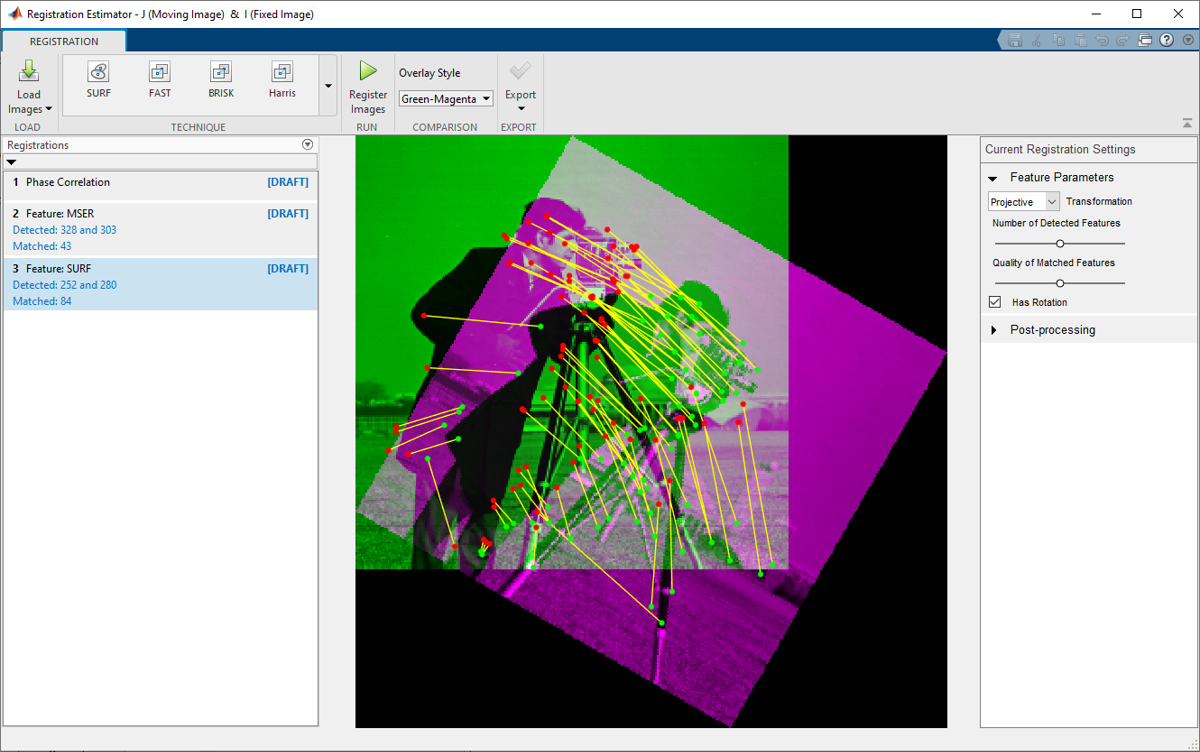

Run the three default registration trials with the default settings. Click each trial in the history list, then click **Register Images**.

After the registration finishes, the trial displays a quality score and computation time. The quality score is based loosely on the [`ssim`](docid:images_ref#bt5rkbx-1) function and provides an overall estimate of registration quality. A score closer to 1 indicates a higher quality registration. Different registration techniques and settings can yield similar quality scores but show error in different regions of the image. Inspect the image overlay to confirm which registration technique is the most acceptable. Colors in the image overlay indicate residual misalignment.

Note: due to randomness in the registration optimizer, the quality score, registered image, and geometric transformation can vary slightly between trials despite identical registration settings.

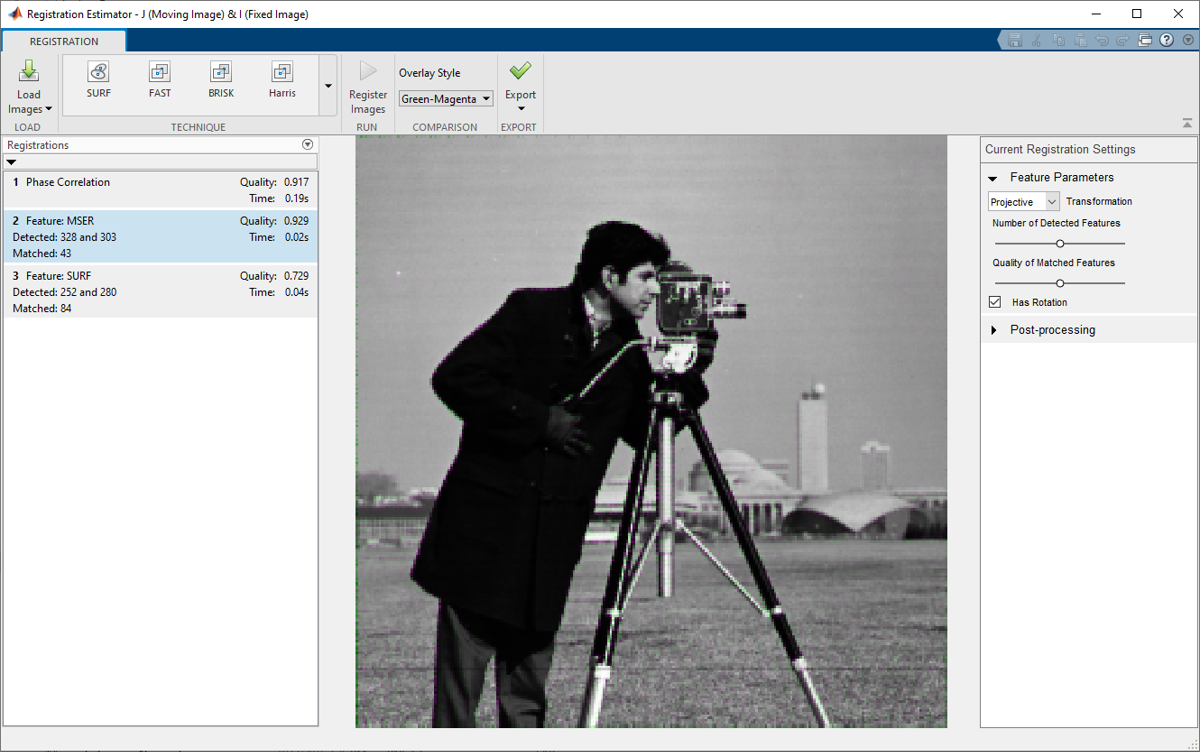

## Refine Registration Settings

After you have an initial registration estimate, adjust registration settings to improve the quality of the alignment. For more information on available settings, see [Tune Registration Settings in Registration Estimator App](docid:images_ug#bvnaqu_-1). If you know the conditions under which the images were obtained, then you can select a different transformation type or clear the **Has Rotation** option. Post-processing using nonrigid transformations is available for advanced workflows.

Adjust the settings of the MSER trial. Try increasing the number of detected features and the quality of matched features independently to see if either improves the quality of the registration.

To increase the number of detected features, click the `Feature: MSER` trial, numbered 2, in the history list. In the Current Registration Settings panel, drag the **Number of Detected Features** slider to the right. When you change the setting, the app creates a new trial, numbered 2.1, in the history list. The image overlay shows more matched features, as expected.

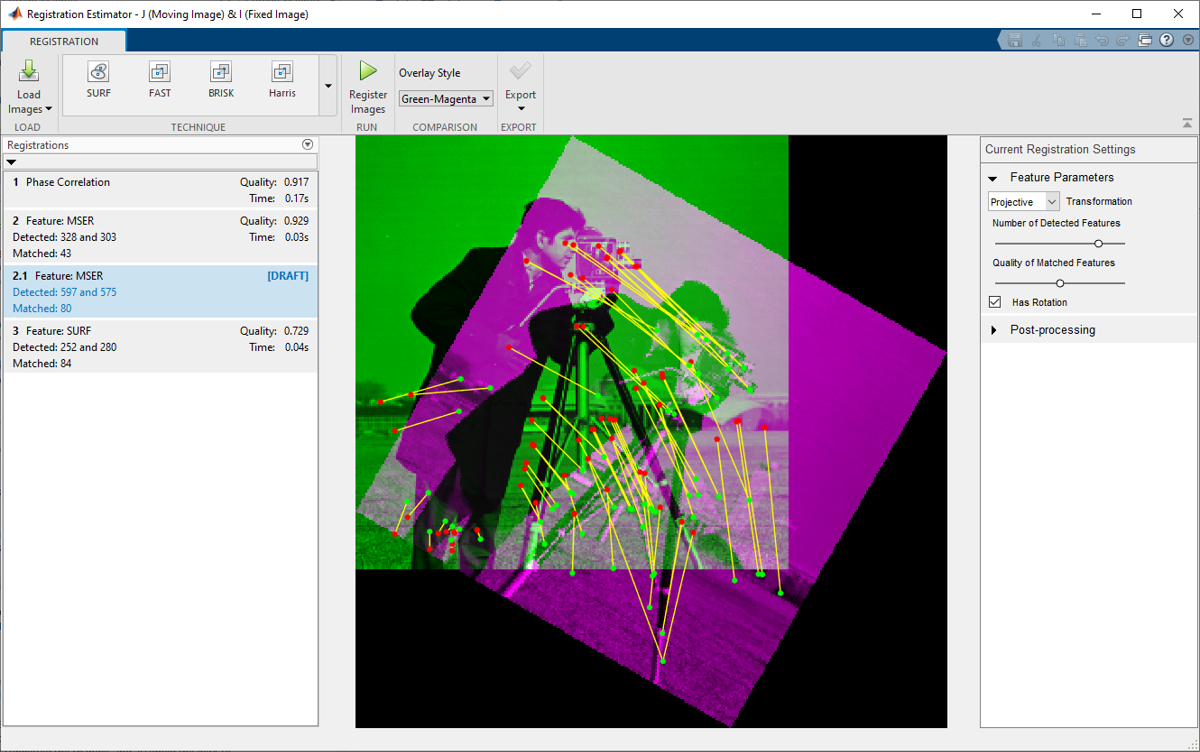

To run the registration with these settings, click **Register Images**. The quality metric of this trial is less than the quality of the original MSER trial with the default number of matched features. The image overlay of this trial has an overall magenta tint and a thick green strip along the top of the man's head. Therefore, increasing the number of detected features from 43 to 80 does not improved the quality of the registration.

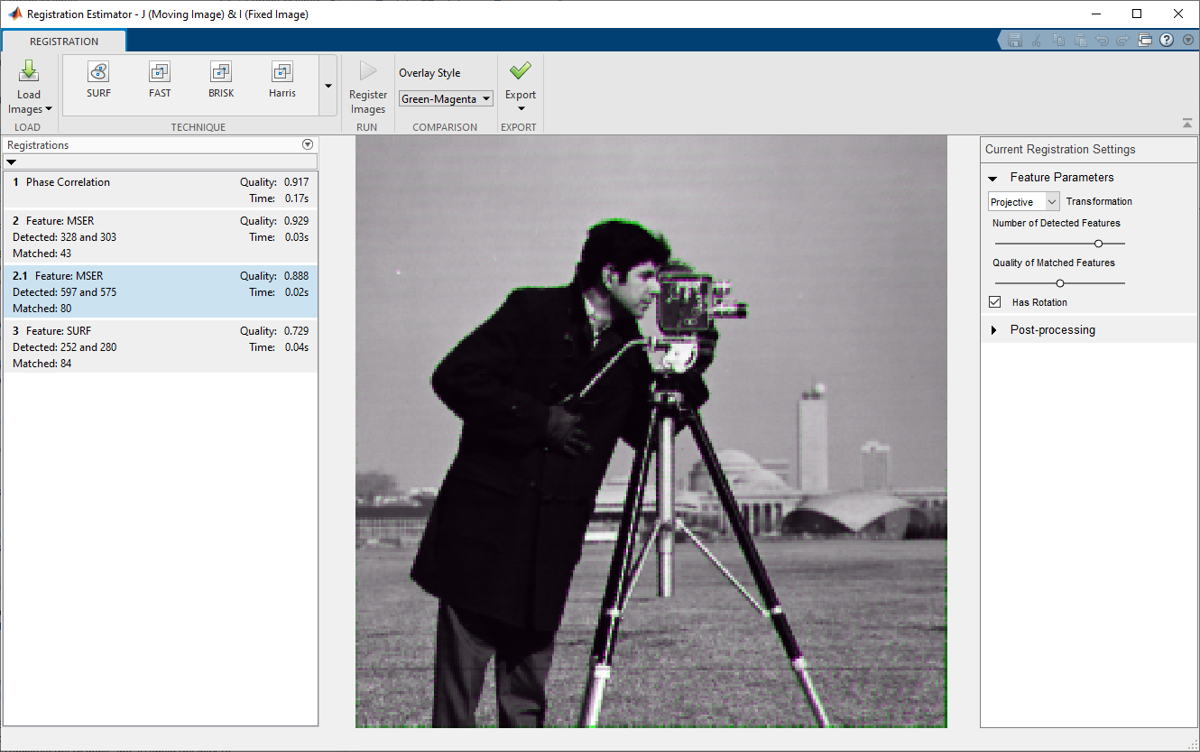

To see the effect of increasing the quality of matched features, click the `Feature: MSER` trial 2 (not 2.1) in the history list. In the **Current Registration Settings** panel, drag the **Quality of Matched Features** slider to the right. When you change the setting, the app creates a new trial, numbered 2.2, in the history list. The image overlay displays a smaller number of high quality matched points.

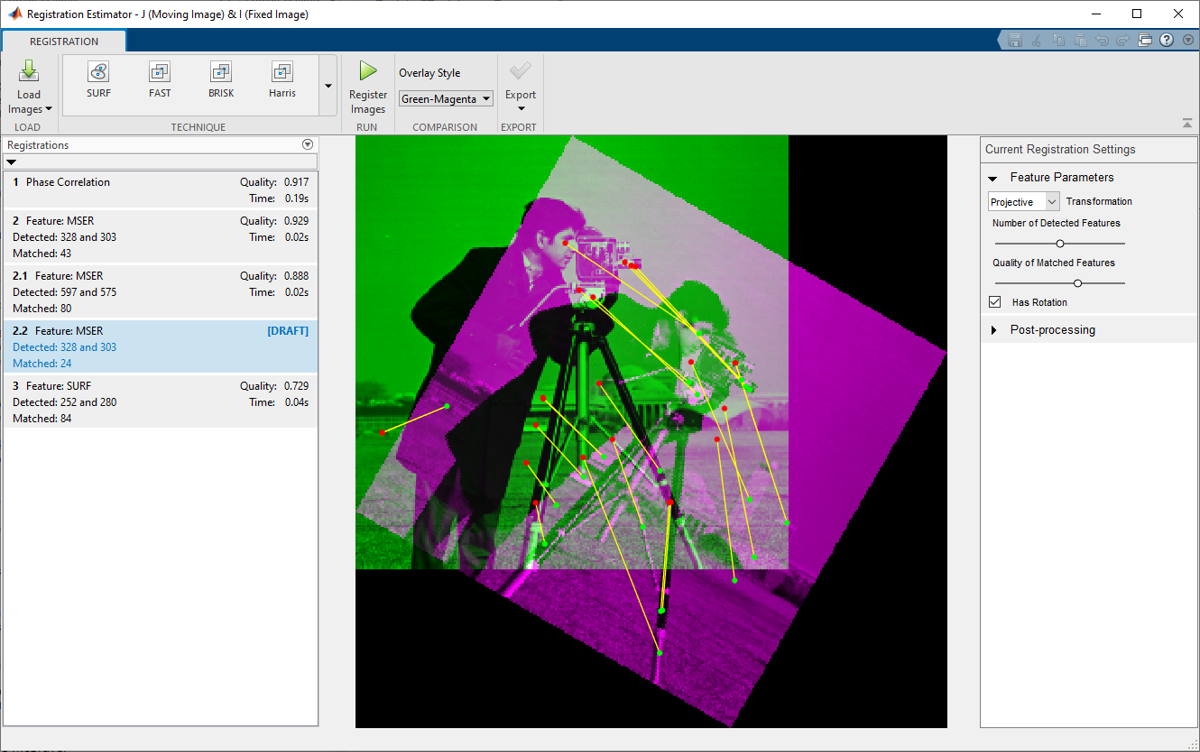

To see the registration with these settings, click **Register Images**. Compared to the other MSER trials, this trial has the best quality score. There is not a noticeable difference in the visual quality of the image compared to the original MSER trial with default settings. If you want to see which pixels differ between the default MSER trial and this trial, change the overlay style to Difference and toggle between the two trials.

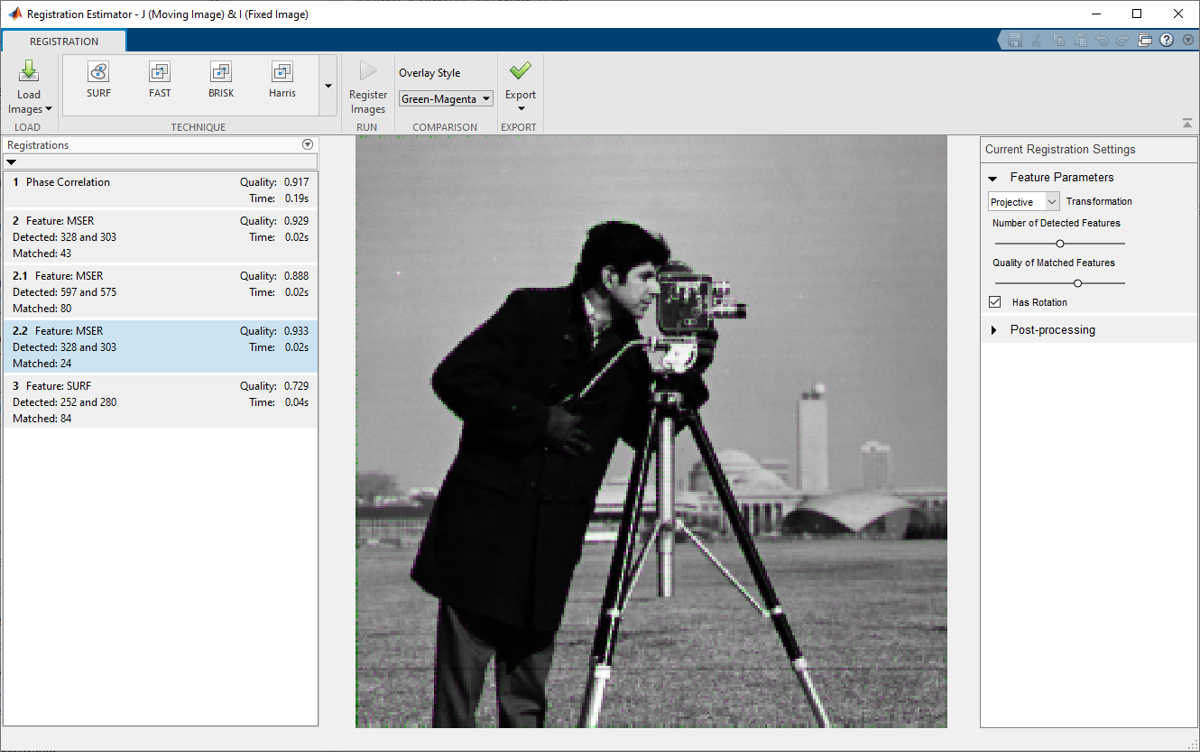

## Export Registration Results

When you find an acceptable registration, export the registered image and the geometric transformation to the workspace. You can use the registration results to apply a similar registration to multiple frames in an image sequence. To learn more, see [Export Results from Registration Estimator App](docid:images_ug#bvn5l5a).

This example exports trial 2.2 because it has the best quality score and no severe regions of misalignment. Click trial 2.2 in the history list, then click **Export** and select** Export Images**. In the **Export to Workspace** dialog box, assign a name to the registration output. The output is a structure that contains the final registered image and the geometric transformation.

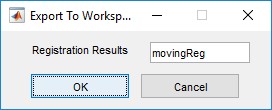

*Copyright 2019 The MathWorks, Inc.*